# Seeding the random number generation

rng(1);
start_sequence_length = 32;
starter_sequence=sign(sign(randn(start_sequence_length,1))+1i*sign(randn(start_sequence_length,1)));

rng(42);
N=10000;%-100*2; % Length of the data
txname='tx_rrc2_pw50.dat';

T = 50; % Symbol Period
span = 20;
rolloff = 0.5

rolloff = 0.5000

rrc = rcosdesign(rolloff,span,T, 'sqrt')   % creates a root-raised cosine 

rrc =     0.2256    0.2252    0.2227    0.2182    0.2118    0.2033    0.1930    0.1808    0.1669    0.1514    0.1344    0.1160    0.0964    0.0757    0.0542    0.0319    0.0091   -0.0140   -0.0372   -0.0603   -0.0832   -0.1055   -0.1272   -0.1480   -0.1677   -0.1861   -0.2032   -0.2186   -0.2323   -0.2441   -0.2539   -0.2617   -0.2672   -0.2706   -0.2716   -0.2703   -0.2667   -0.2607   -0.2525   -0.2421   -0.2296   -0.2150   -0.1984   -0.1801   -0.1601   -0.1386   -0.1158   -0.0918   -0.0670   -0.0415


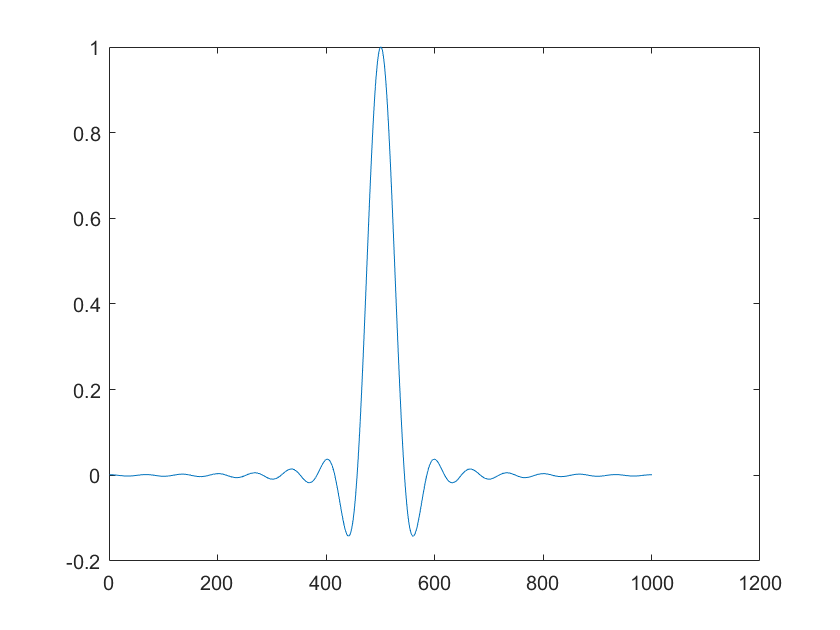

                                      % filter which when combined with a 
                                      % matched filter results in 
                                      % zero crossings every 
                                      % T. Rolloff factor of 0.5
                                      % 20 x 3 samples are returned 
                                      % (in theory the raised cosine
                                      % impulse response is infinite, but
                                      % is truncated to T x 20 samples)
%p_f = rrc ./ h_f;
rrc = rrc ./ max(rrc);
plot(rrc)

## Generate complex white noise pulses TX Data

dat=sign(sign(randn(N,1))+1i*sign(randn(N,1)));%*(1/sqrt(2));
% negative = -1*ones(100,1)-1i*ones(100,1);
% positive = 1*ones(100,1)+1i*ones(100,1);
dat= [starter_sequence.' dat.'].'

dat =   -0.7071 + 0.7071i
   0.7071 - 0.7071i
  -0.7071 + 0.7071i
  -0.7071 + 0.7071i
  -0.7071 - 0.7071i
  -0.7071 + 0.7071i
  -0.7071 + 0.7071i
   0.7071 - 0.7071i
  -0.7071 + 0.7071i
   0.7071 - 0.7071i


x_us=upsample(dat,T);
%pulse=ones(100,1);
pulse = rrc;
x=conv(x_us,pulse, 'same');

write_usrp_data_file(x,txname)

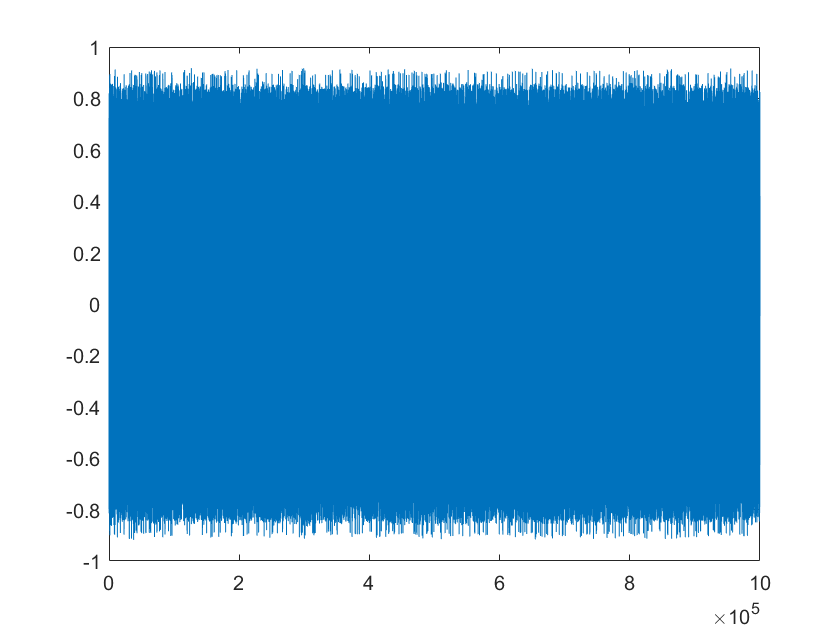

plot(real(x))

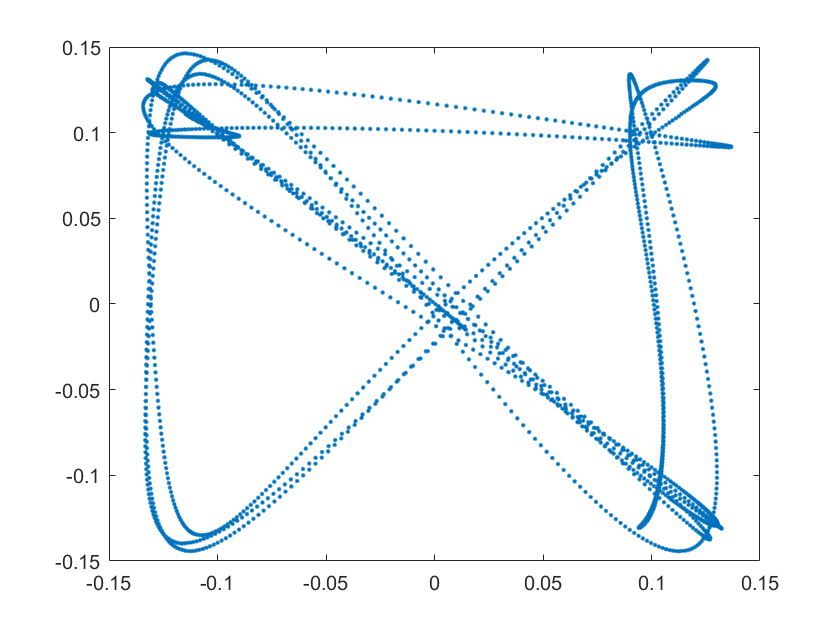

plot(real(x), imag(x), '.')

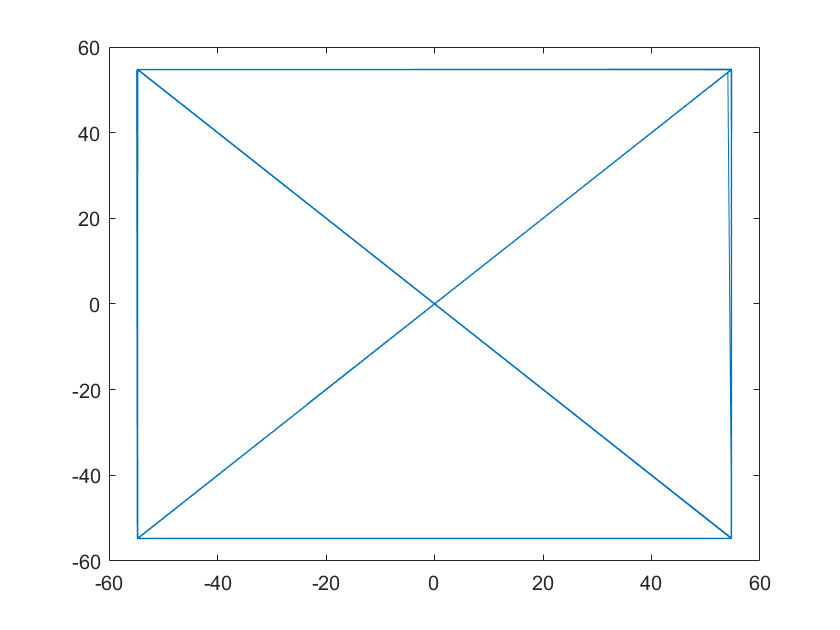

y1 = conv(x, rrc, 'same');
y = downsample(y1, T);
plot(y)

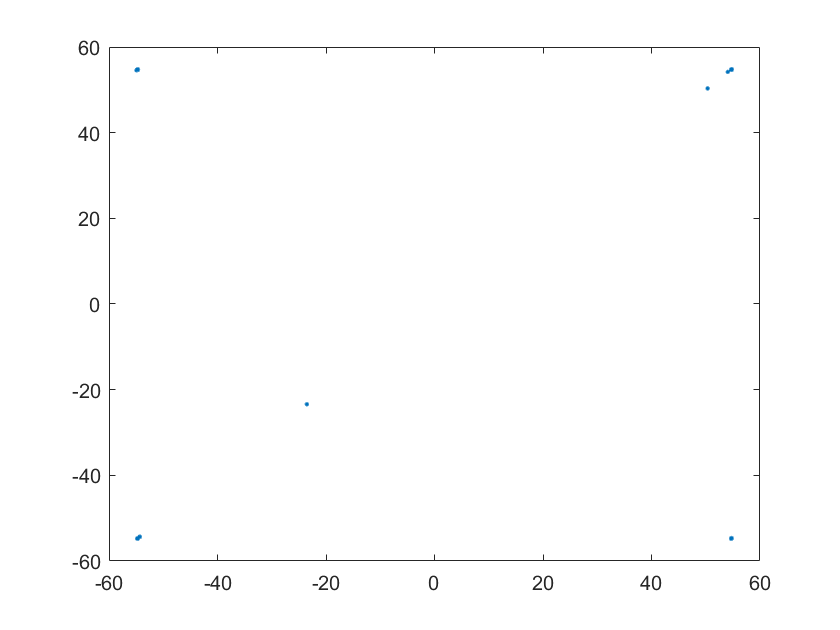

plot(real(y), imag(y), '.')


error_real=sign(real(y))-sign(real(dat));
error_imag=sign(imag(y))-sign(imag(dat));
err_real = length(find(error_real~=0));
err_imag = length(find(error_imag~=0));

% Sum errors and calculate error rate
err_total = err_real + err_imag;
err_rate=err_total/(length(y)*2);
err_rate

err_rate = 0

a=[1;2;3];
b=[4;5;6;7];
c=[a' b']';

## Generate a cosine

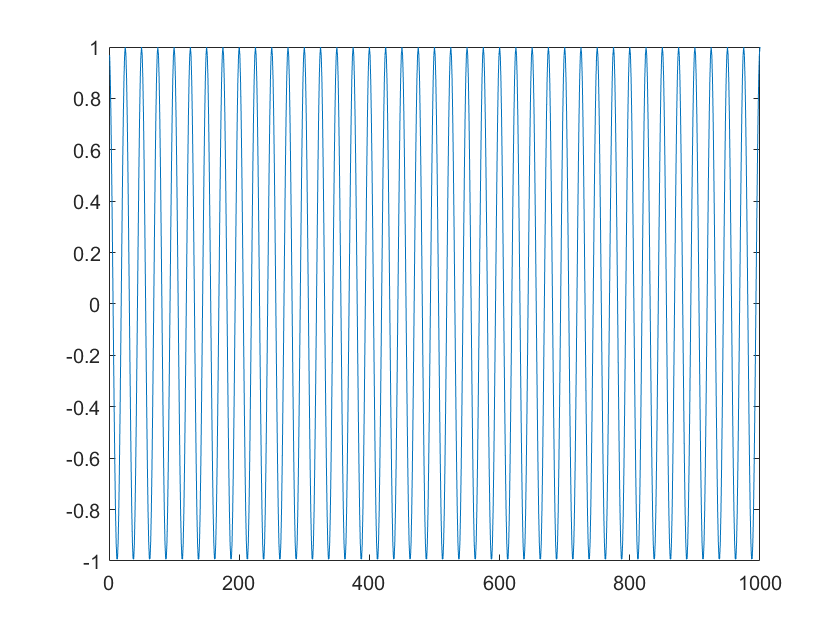

x=1:N;
cos_Dat=cos(2*pi/25*x);
write_usrp_data_file(cos_Dat)
plot(cos_Dat)


%write_usrp_data_file(x,txname)

err_rate = 0.4370